# **Ejercicio 2.1: Modelado de sistema Volterra-Lotka**

**a)**

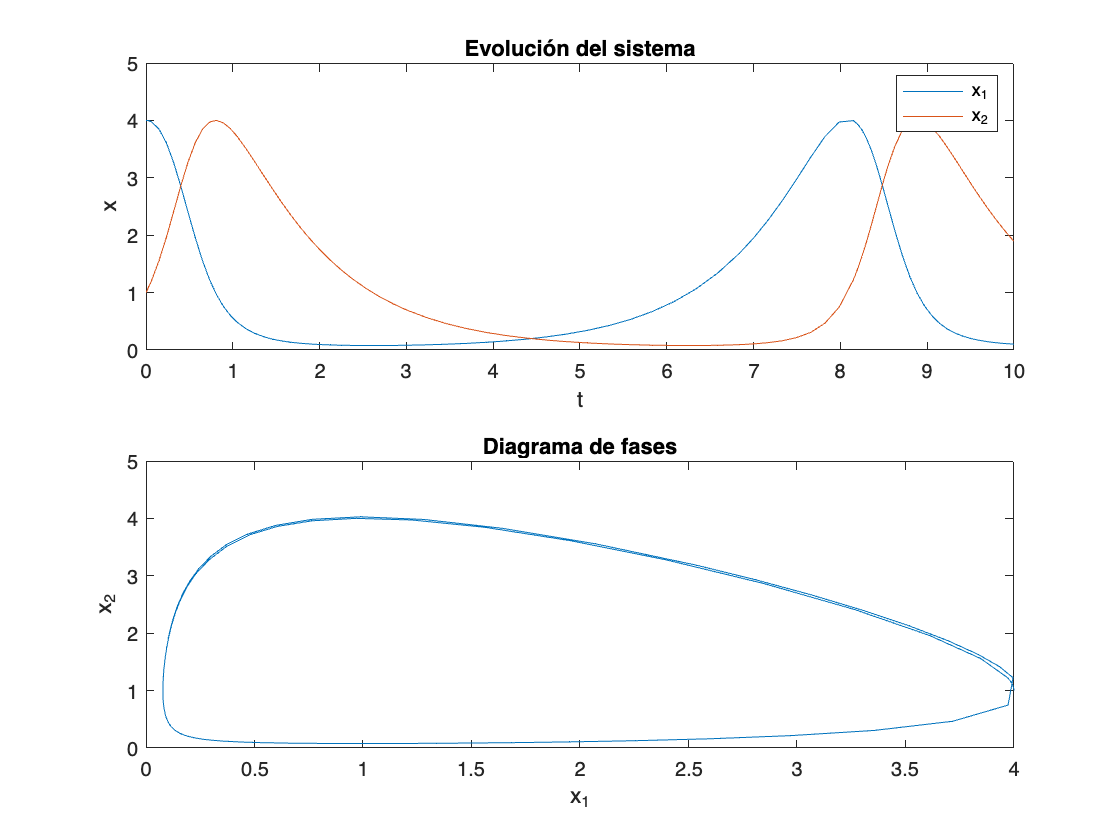

%Definición de parámetros del sistema, intervalos de evaluación y estado
%inicial

[a, b, c, d] = deal(1); %deal(3, 1, 0.2, 0.7);
x0 = [4; 1];
tspan = [0,10];

%Integración de las ecuaciones del sistema
[t, x] = ode45(@(t, x)lotkavolterra(t, x, a, b, c, d), tspan, x0);

%Gráficas
figure(1);
subplot(2, 1, 1)
plot(t, x)
title("Evolución del sistema")
legend("x_1", "x_2")
ylabel("x")
xlabel("t")

subplot(2, 1, 2)
plot(x(:,1), x(:,2))
title("Diagrama de fases")
ylabel("x_2")
xlabel("x_1")

**b)**

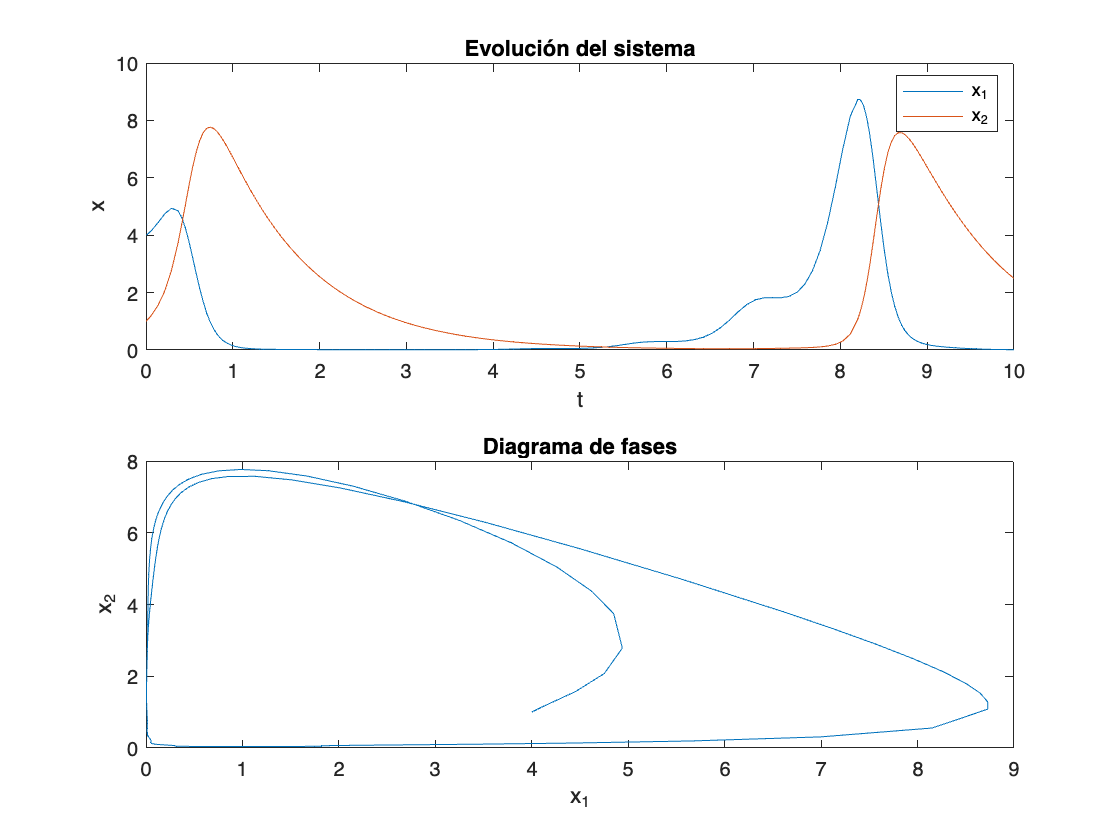

a0 = 3;
f = 5;

[t2, x2] = ode45(@(t, x)lotkavolterra2(t, x, a0, b, c, d, f), tspan, x0);

figure(2);
subplot(2, 1, 1)
plot(t2, x2)
title("Evolución del sistema")
legend("x_1", "x_2")
ylabel("x")
xlabel("t")

subplot(2, 1, 2)
plot(x2(:,1), x2(:,2))
title("Diagrama de fases")
ylabel("x_2")
xlabel("x_1")

**Funciones**

function xdot = lotkavolterra(t, x, a, b, c, d)
    
    %El sistema es autónomo pero se necesita el parámetro t para que funcione ODE45.
    %La entrada y la salida son vectores de dos filas y una columna. 
    
    xdot(1,1) = a * x(1,1) - c * x(1,1) * x(2,1);
    xdot(2,1) = -b * x(2,1) + d * x(1,1) * x(2,1);

end


function xdot2 = lotkavolterra2(t, x, a, b, c, d, f)
    
    %Ahora a deja de ser un parámetro fijo a ser una función periódica de
    %frecuencia angular f

    a2 = (a/2 * sin(f*t) + a/2);
    xdot2 = lotkavolterra(t, x, a2, b, c, d);
    
end